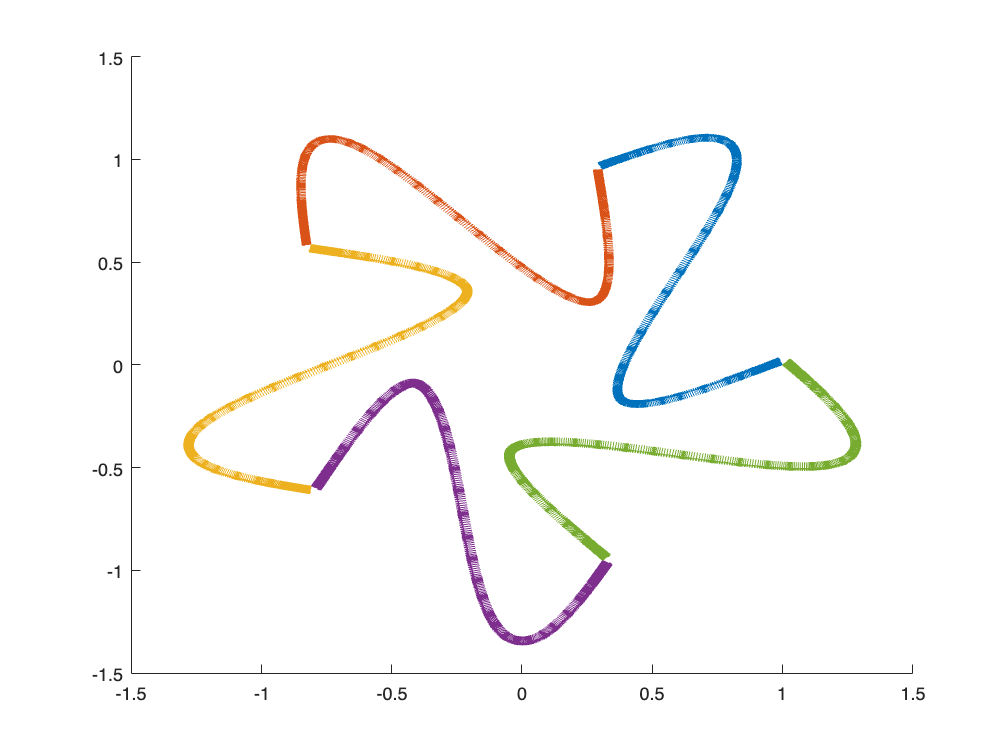

clear all

verts = exp(1i*2*pi*(0:4)/5);
verts = [real(verts);imag(verts)];

edge2verts = [-1, 1, 0, 0, 0; ...
               0,-1, 1, 0, 0; ...
               0, 0,-1, 1, 0; ...
               0, 0, 0,-1, 1; ...
               1, 0, 0, 0,-1];
edge2verts = sparse(edge2verts);
amp = 0.5;
frq = 6;

for icurve = 1:size(edge2verts,1)
    fchnks{icurve} = @(t) sinearc(t,amp,frq);
end
%fchnks = {};

prefs      = [];
prefs.chsmall = 1d-4;
prefs.maxchunklen = 1;

[cgrph] = chunkgraph(verts,edge2verts,fchnks,prefs);

vstruc = procverts(cgrph);
rgns = findregions(cgrph);
cgrph = balance(cgrph);

figure
quiver(cgrph)


chunkr1 = cgrph.echnks(1);
chunkr2 = cgrph.echnks(2);
chunkr3 = cgrph.echnks(3);
chunkr4 = cgrph.echnks(4);
chunkr5 = cgrph.echnks(5);

m = 4;
m2 = -4;

w = 4;
w2 = 4;

xi=2;

E=2;


fkern =  @(source,target) circle_rcip_kern2(source,target,E,m,w,xi) - circle_rcip_kern2(source,target,E,m2,w2,xi);


opts = [];
opts.nonsmoothonly = false;
opts.rcip = true;
[sysmat] = chunkermat(cgrph,fkern,opts);
sysmat = sysmat + eye(size(sysmat,2));



source = [0;1.5];


rhs1 = (2*pi)^(1/2) * diracgreeneval_circle(chunkr1,E,m,w,xi,source);
rhs1 = rhs1(:,1);

rhs2 =  (2*pi)^(1/2) * diracgreeneval_circle(chunkr2,E,m,w,xi,source);
rhs2 = rhs2(:,1);

rhs3 =  (2*pi)^(1/2) * diracgreeneval_circle(chunkr3,E,m,w,xi,source);
rhs3 = rhs3(:,1);

rhs4 =  (2*pi)^(1/2) * diracgreeneval_circle(chunkr4,E,m,w,xi,source);
rhs4 = rhs4(:,1);

rhs5 =  (2*pi)^(1/2) * diracgreeneval_circle(chunkr5,E,m,w,xi,source);
rhs5 = rhs5(:,1);


RHS = [rhs1;rhs2;rhs3;rhs4;rhs5];


density = sysmat \ RHS;

% generate some targets...

xs = -2:0.01:2;
ys = -2:0.01:2;
[X,Y] = meshgrid(xs,ys);
targets = [X(:).';Y(:).'];

srcinfo = [];
srcinfo.sources = cgrph.r(:,:);

Unable to resolve the name 'cgrph.r'.

we = weights(cgrph);
n = normals(cgrph);

% a quick hack to find the interior points

srcinfo.dipstr = we(:).';
srcinfo.dipvec = n(:,:); 
eps = 1E-8;
pg  = 0;
pgt = 1;
[U] = lfmm2d(eps,srcinfo,pg,targets,pgt);
U = U.pottarg;
in = find(abs(U-2*pi)<pi/10);



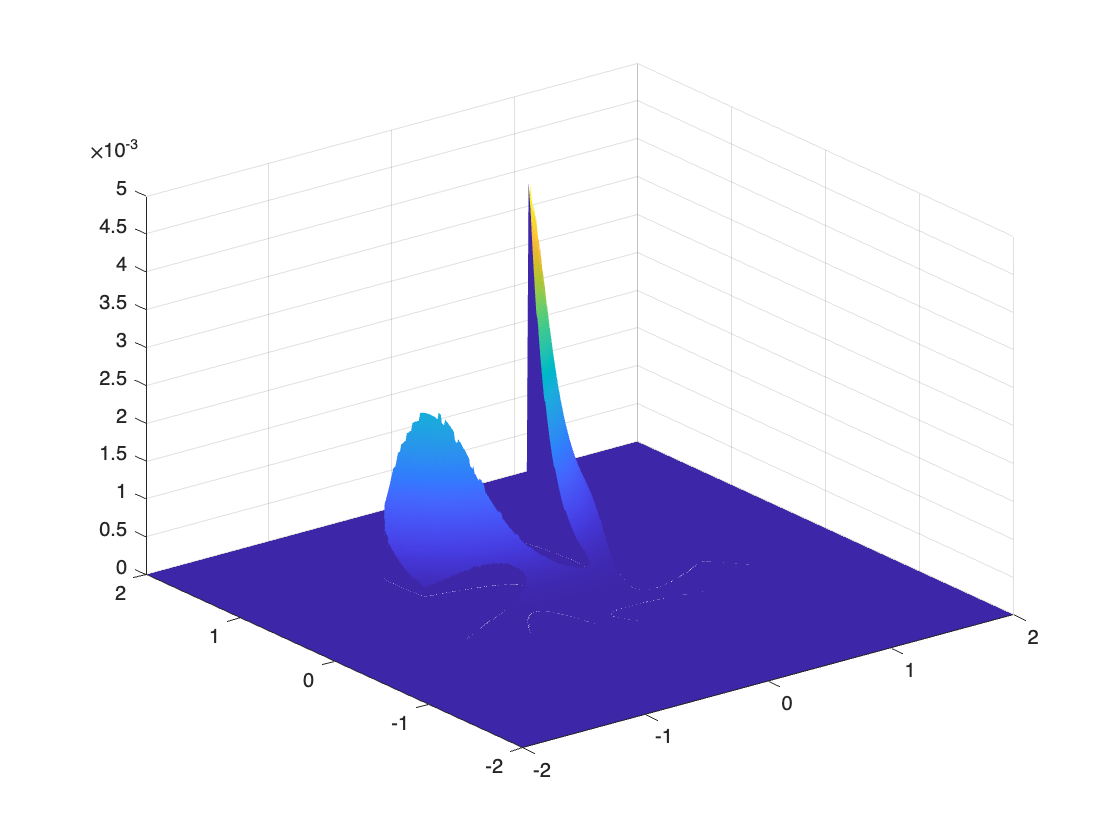

u_in = zeros(size(targets,2),1);

true_sol = diracgreeneval_cross(targets(:,in),E,m,w,xi,source);
true_sol = true_sol(:,1);
true_sol = true_sol(1:4:end);

u_in (in) = true_sol;
u_in = reshape(u_in,size(X));

figure
h = surf(X,Y,abs(u_in));
set(h,'EdgeColor','none');

[lens,~] = size(density);
rho1 = density(1:lens/5);
rho2 = density(lens/5+1: lens/5*2);
rho3 = density(lens/5*2+1: lens/5*3);
rho4 = density(lens/5*3+1: lens/5*4);
rho5 = density(lens/5*4+1: lens);



eval_in = dirackernelevalmat_cross(chunkr1,E,m,w,xi,targets(:,in)) * rho1 + dirackernelevalmat_cross(chunkr2,E,m,w,xi,targets(:,in)) * rho2 +...
    + dirackernelevalmat_cross(chunkr3,E,m,w,xi,targets(:,in)) * rho3 + dirackernelevalmat_cross(chunkr4,E,m,w,xi,targets(:,in)) * rho4 +... 
    + dirackernelevalmat_cross(chunkr5,E,m,w,xi,targets(:,in)) * rho5



Z = zeros(size(targets,2),1);
Z(in) = eval_in(1:4:end);
Z = reshape(Z,size(X));

figure

h2 = surf(X,Y,abs(Z));
set(h2,'EdgeColor','none');






error = zeros(size(targets,2),1);
error(in) = abs(eval_in(1:4:end) - true_sol);
error = reshape(error, size(X));


figure

h3 = surf(X,Y, error);
set(h3, 'EdgeColor', 'None');



